# FUELREGULARIZED

Fit and evaluate regularized linear models of fuel economy.

## Load data

load carEcon

## Make numeric variables out of tabular data (including categoricals)

[X,names] = cattable2mat(carData);
Xtrain = X(idxTrain,:);
Xtest = X(~idxTrain,:);
ytrain = carTrain.FuelEcon;
ytest = carTest.FuelEcon;

## Perform ridge regression on fuel economy

Define a range of the regularization parameter

lambda = 0:200;
b = ridge(ytrain,Xtrain,lambda);

View the effect of `lambda` on the coefficients and error

figure
subplot(2,1,1)
plot(lambda,b')
subplot(2,1,2)

To make predictions with original data, need to shift coefficients back to unscaled data (`RIDGE` normalizes data by default)

m = mean(Xtrain);
s = std(Xtrain,0,1)';

Note `b` is a matrix (one column for each value of `lambda`)

b = b./s;

Calculate constant term (from scaling)

intercept = mean(ytrain) - m*b;

Make predictions

Y = intercept + Xtest*b;

Note `Y` is a matrix (one column for each value of `lambda`)

Need to calculate MSE for each column

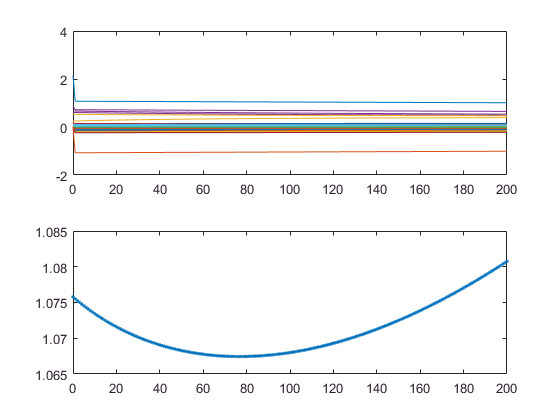

mse = mean((Y - ytest).^2);
plot(lambda,mse,'.-')

Evaluate best fit

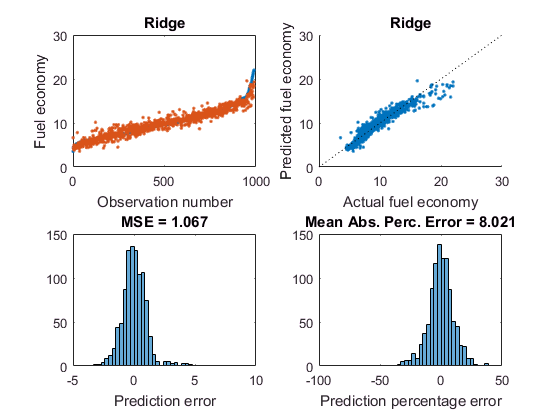

[~,k] = min(mse);
evaluatefit(ytest,Y(:,k),'Ridge')

## Perform lasso regression on fuel economy

Different interpretation of `lambda` (scaling by number of observations)

lambda = lambda/height(carTrain);
[b,fitinfo] = lasso(Xtrain,ytrain,'Lambda',lambda);

View the effect of `lambda` on the coefficients and error

figure
subplot(2,1,1)
plot(lambda,b')
subplot(2,1,2)

MSE stored in `fitinfo` (no need to calculate)

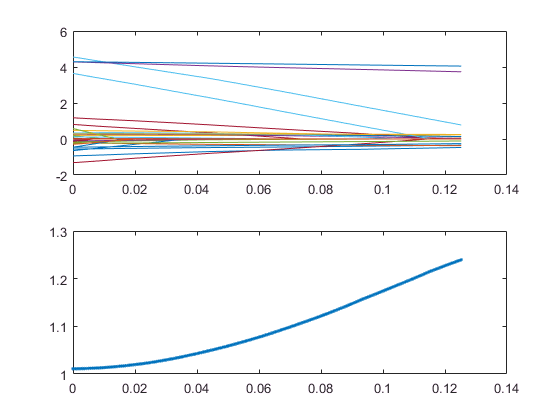

plot(fitinfo.Lambda,fitinfo.MSE,'.-')

Evaluate best fit

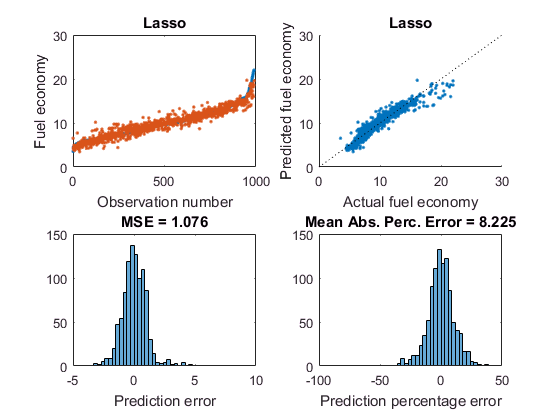

[~,k] = min(fitinfo.MSE);
Y = fitinfo.Intercept(k) + Xtest*b(:,k);
evaluatefit(ytest,Y,'Lasso')

## Perform elastic net regression on fuel economy

[b,fitinfo] = lasso(Xtrain,ytrain,'Lambda',lambda,'Alpha',0.6);

View the effect of `lambda` on the coefficients and error

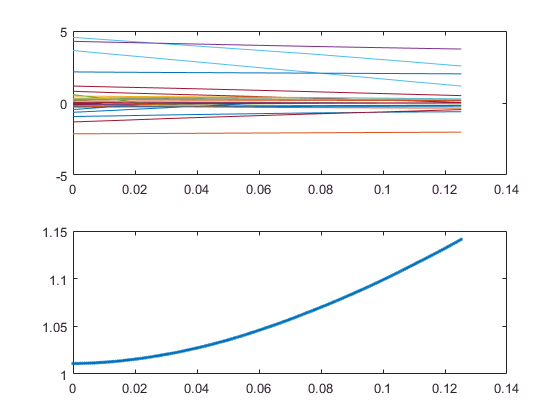

figure
subplot(2,1,1)
plot(lambda,b')
subplot(2,1,2)
plot(fitinfo.Lambda,fitinfo.MSE,'.-')

Evaluate best fit

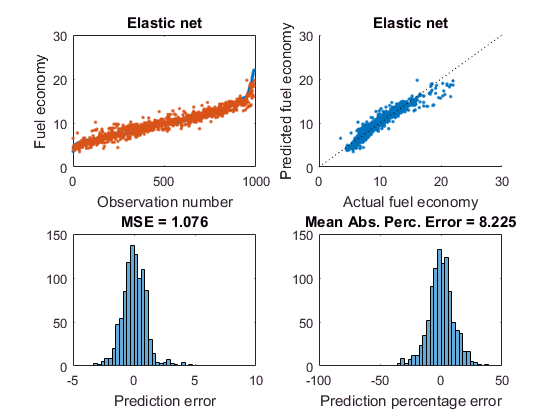

[~,k] = min(fitinfo.MSE);
Y = fitinfo.Intercept(k) + Xtest*b(:,k);
evaluatefit(ytest,Y,'Elastic net')